# Laboratory 2

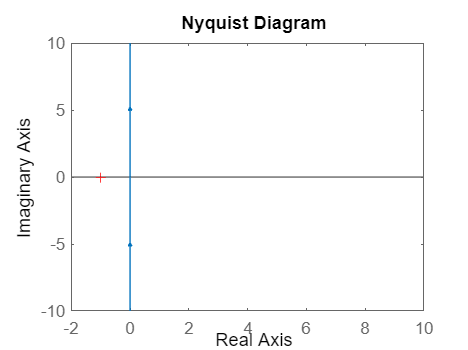

H = tf(4,[1,0]);
nyquist(H)

### Case 1

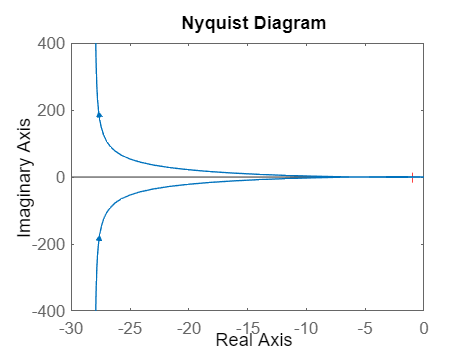

den = conv([1 2 0],[1 5]); % use conv function to obtain the coefficients of the denominator
H = tf(400,den); % declare the transfer function
nyquist(H); % plot the Nyquist diagram

shg; % bring the plot in the active window position

%% the compact form
nyquist(400,conv([1 2 0],[1 5]))

%% zoom on a certain area
axis([-10 0 -2 2]) % See Figure 2

%% how to plot unity circle
hold; % keep the nyquist diagram

Current plot held


x = 0:0.1:2*pi; 
plot(sin(x),cos(x),'--r');
shg; % plot a red, dashed line unity circle
hold; % leave all the plots

Current plot released


### Case 2

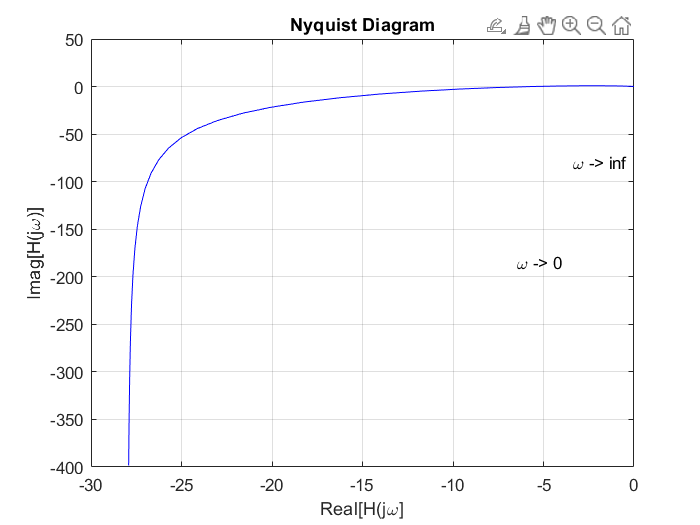

close all; clear
H = tf(400,conv([1 2 0],[1 5]));
[real_part, imag_part] = nyquist(H,'v');
real_part_vect = squeeze(real_part); %Remove singleton dimensions
imag_part_vect = squeeze(imag_part); %Remove singleton dimensions
plot(real_part_vect, imag_part_vect,'b'); grid; shg
title('Nyquist Diagram');
xlabel('Real[H(j\omega]');ylabel('Imag[H(j\omega)]')
% click on the graphics as in Figure 4
[x1,y1] = ginput(1); % coordinates for Low Freq. Region
text(x1,y1,'\omega -> 0'); % place the text on LFR
% click on the graphics as in Figure 4
[x2,y2] = ginput(1); % coordinates for Hihg Freq. Region
text(x2,y2,'\omega -> inf'); % place the text on HFR, see figure 3